A simple and widely used method to read and use nifti files like the Julich-Brain Atlas is the Statistical Parametric Mapping Toolbox (SPM), which can be integrated into Matlab for free.

For this we first check if SPM is integrated in Matlab. In the output there should be a line "Statistical Parametric Mapping Toolbox".

If this is not the case, please install SPM first.

ver

-----------------------------------------------------------------------------------------------------
MATLAB Version: 9.10.0.1739362 (R2021a) Update 5
MATLAB License Number: 599818
Operating System: Microsoft Windows 10 Enterprise Version 10.0 (Build 19043)
Java Version: Java 1.8.0_202-b08 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode
-----------------------------------------------------------------------------------------------------
MATLAB                                                Version 9.10        (R2021a)
Image Processing Toolbox                              Version 11.3        (R2021a)
MATLAB Compiler                                       Version 8.2         (R2021a)
MATLAB Compiler SDK                                   Version 6.10        (R2021a)
Parallel Computing Toolbox                            Version 7.4         (R2021a)
RICOH MEG Reader toolbox for MATLAB                   Version 1.0.2               
Signal Processing Toolbox               

First load the header information of the 4D nifti file

julich_brain_colin27_v2_9=spm_vol('JULICH_BRAIN_CYTOARCHITECTONIC_MAPS_2_9_MNI152_2009C_NONL_ASYM.pmaps.nii');

julich_brain_colin27_v2_9 is a struct array with 302 fields. The 302 fields result from the fact that probability maps of 151 areas are included, each separated by left and right hemisphere. 

The indexes of the maps and their HBP labels are stored in the appropriate text file (JULICH_BRAIN_CYTOARCHITECTONIC_MAPS_2_9_MNI152_2009C_NONL_ASYM.txt).

For example, if we want to load the map for the left frontal pole, the following line of the text file is relevant for us:

"135 Area Fp1 (FPole) left". 

The probability map of the area Fp1 (FPole) of the left hemisphere has the index 135. Use e.g. spm_image() to display the map in an interactive window.

SPM12: spm_image (v7573)                           16:04:03 - 04/10/2021
Display JULICH_BRAIN_CYTOARCHITECTONIC_MAPS_2_9_MNI152_2009C_NONL_ASYM.pmaps.nii,135


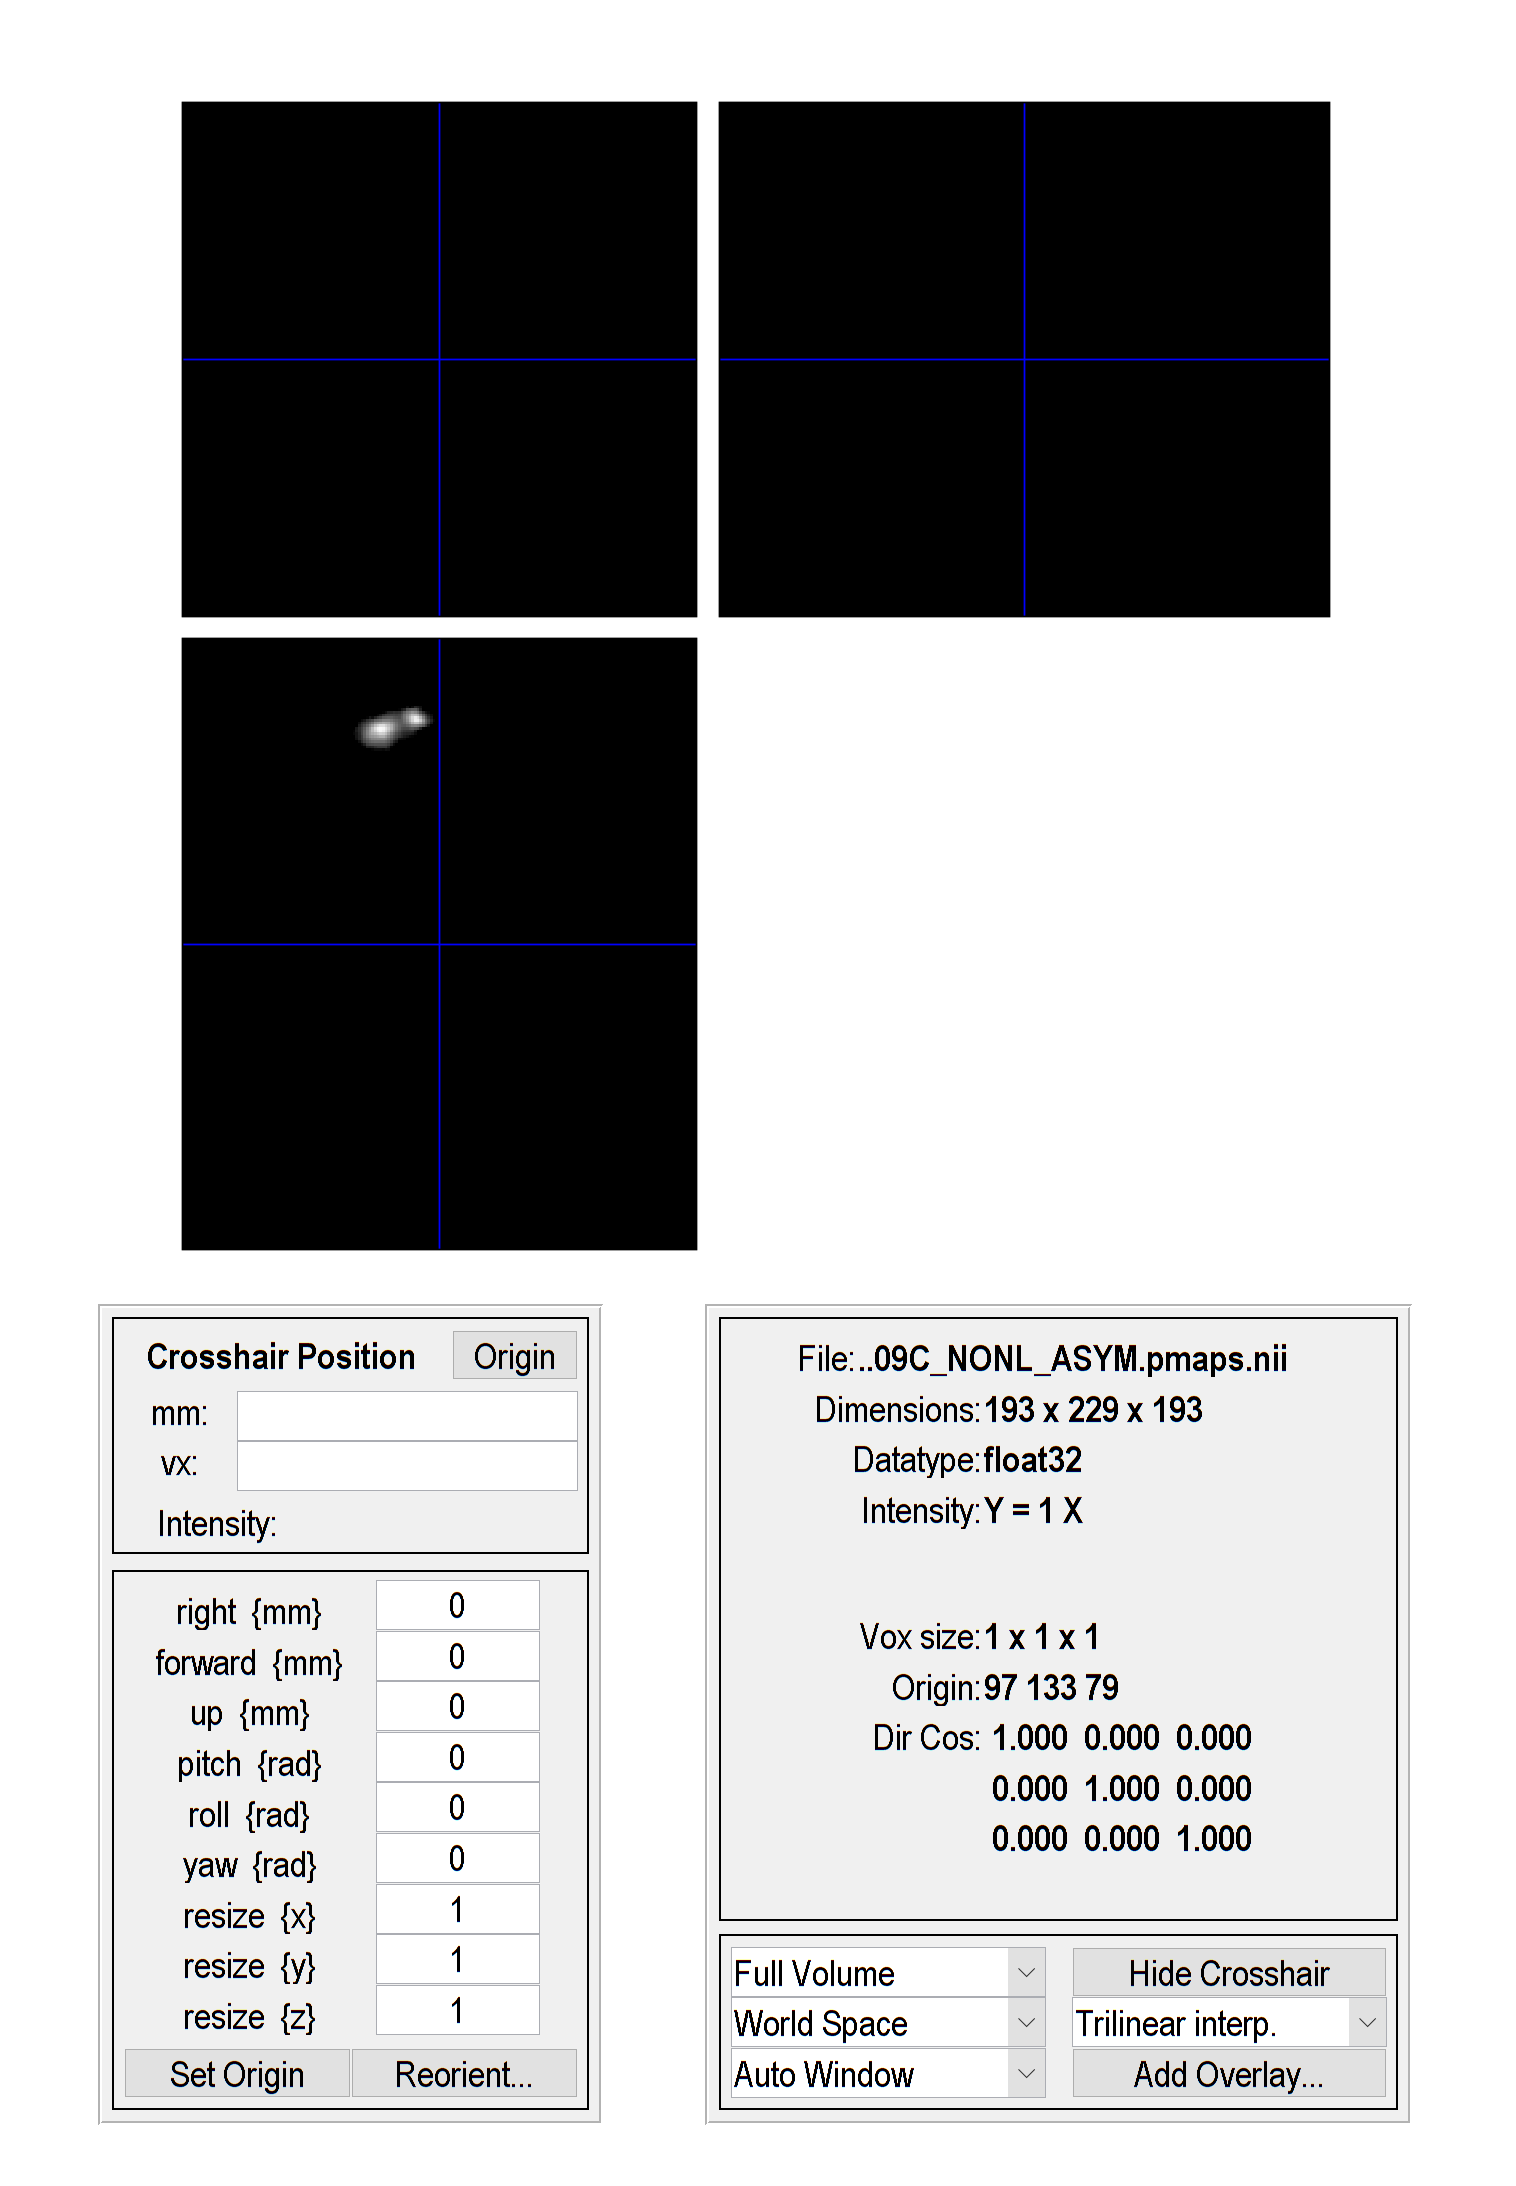

spm_image('Display',julich_brain_colin27_v2_9(135));

Furthermore, the volume of the probability map can be loaded to query simple statistical values.

%read the volume of area Fp1 l
volume_fp1_l=spm_read_vols(julich_brain_colin27_v2_9(135));
%check the dimensions of the dataset
size(volume_fp1_l)

ans =    193   229   193


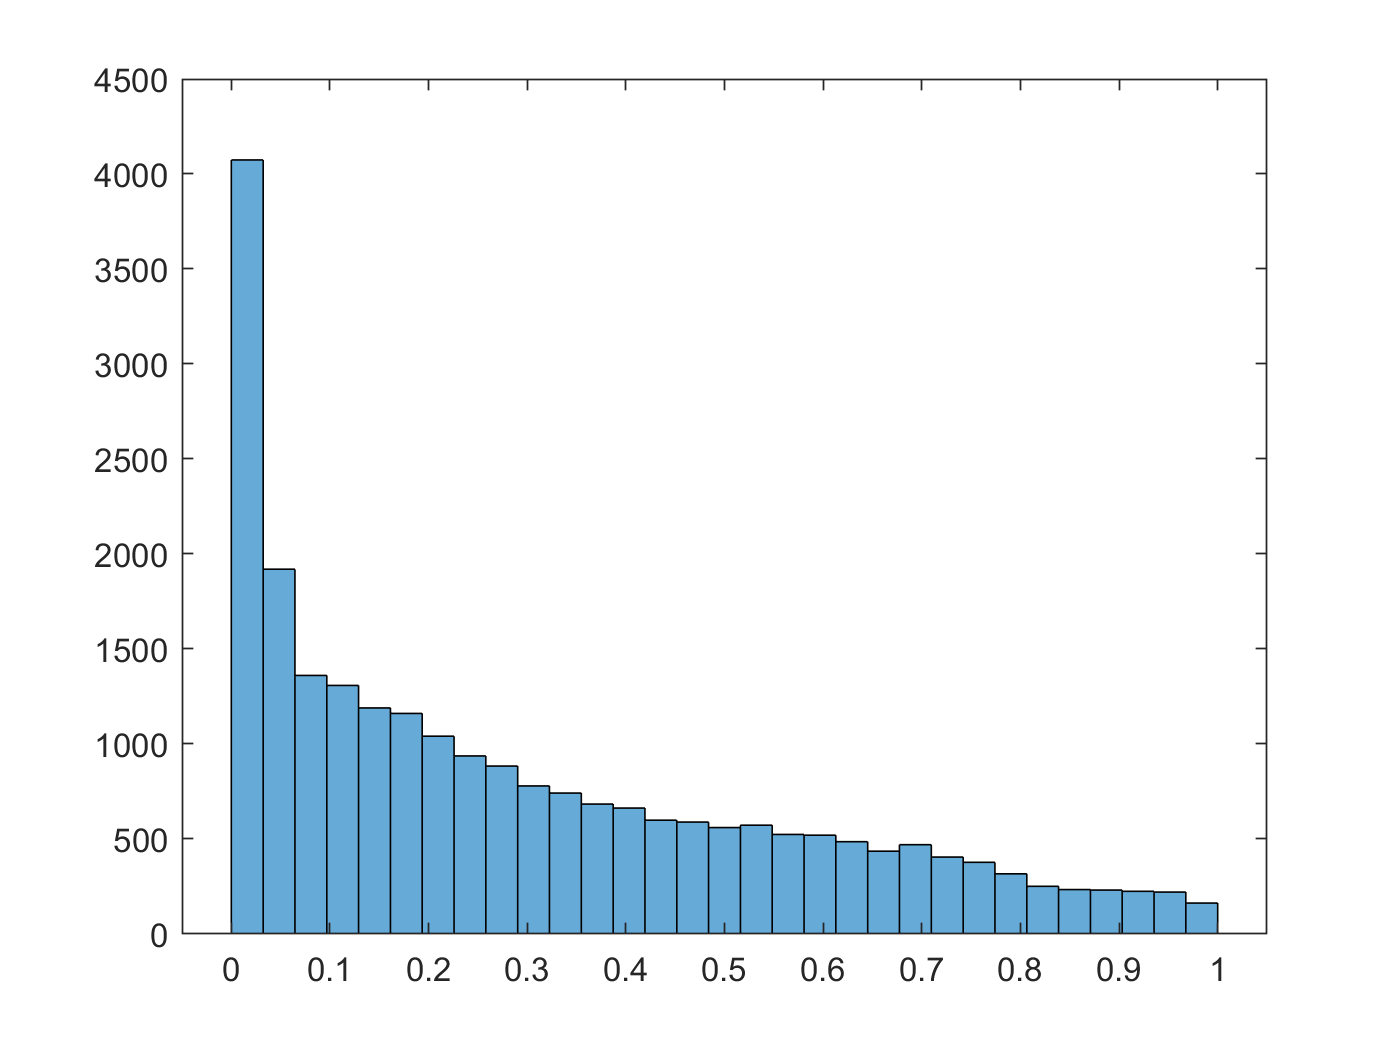

% plot a histogram of the probability distribution
histogram(volume_fp1_l,'BinLimits',[0.0001,1])

% create binary mask of map to measure properties of 3-D volumetric image regions
bwMask = volume_fp1_l;
bwMask(bwMask>0)=1;

stats = regionprops3(bwMask,volume_fp1_l,'all');

for col = 1 : width(stats)
  stats(:, col) 
end

ans = table
    Volume
    ______

    24018 


ans = table
             Centroid         
    __________________________

    195.42    78.042    79.155


ans = table
    BoundingBox 
    ____________

    [1×6 double]


ans = table
                                                                                                                                                                                                                                     SubarrayIdx                                                                                                                                                                                                                                 
    _____________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    {[54 55 56 57 58 

ans = table
          Image       
    __________________

    {45×27×63 logical}


ans = table
    EquivDiameter
    _____________

       35.797    


ans = table
    Extent 
    _______

    0.31378


ans = table
      VoxelIdxList  
    ________________

    {24018×1 double}


ans = table
       VoxelList    
    ________________

    {24018×3 double}


ans = table
       PrincipalAxisLength    
    __________________________

    53.737     40.11    18.328


ans = table
             Orientation         
    _____________________________

    -23.871     81.714    -129.25


ans = table
    EigenVectors
    ____________

    {3×3 double}


ans = table
    EigenValues 
    ____________

    {3×1 double}


ans = table
      ConvexHull  
    ______________

    {188×3 double}


ans = table
       ConvexImage    
    __________________

    {45×27×63 logical}


ans = table
    ConvexVolume
    ____________

       34301    


ans = table
    Solidity
    ________

    0.70021 


ans = table
    SurfaceArea
    ___________

      6049.4   


ans = table
      VoxelValues   
    ________________

    {24018×1 double}


ans = table
         WeightedCentroid     
    __________________________

    195.92     78.24    77.371


ans = table
    MeanIntensity
    _____________

       0.29717   


ans = table
    MinIntensity
    ____________

     1.6322e-07 


ans = table
    MaxIntensity
    ____________

      0.99981   
